# Create and Customize 3-D Vertical Bar Graphs

3-D vertical bar graphs present data with 3-D rectangular bars with heights proportional to the values that they represent.

### Read Temperature Data

We will use `'BostonTemp.mat' `to demonstrate how to create and customize 3-D vertical bar graphs. The MAT-file contains monthly temperature data of Boston, MA (Logan Airport) by the U.S. National Oceanic and Atmospheric Administration between 2000 and 2020. 

load BostonTemp.mat

### Basic 3-D Bar Graph

Visualize the monthly temperature for five years between 2000 and 2020.

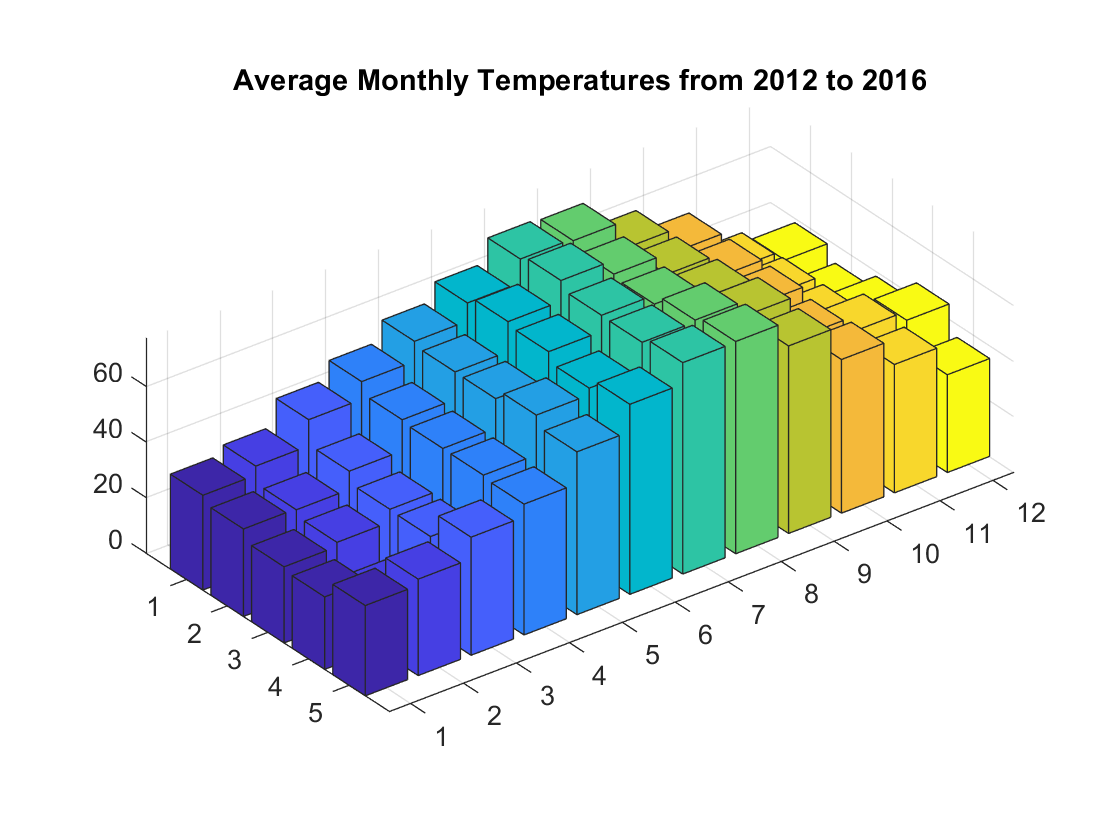

yearIdx = 13;      % Choose the starting year to visualize the monthly temperature for five years.
TempData5Years = Temperatures(yearIdx:yearIdx+4,:);

bar3(TempData5Years);
title(sprintf("Average Monthly Temperatures from %d to %d",Year(yearIdx),Year(yearIdx+4)))

## Customization

### Customize Bar Width and Color

A bar graph can be customized to have user-specified bar width and color. Use the third argument to `bar3` to modify the bar width. Modify the *CData*, and *FaceColor *properties using dot notation. When *CData* is set to *ZData*, the bar color becomes a gradient based on the z-axis temperature values.

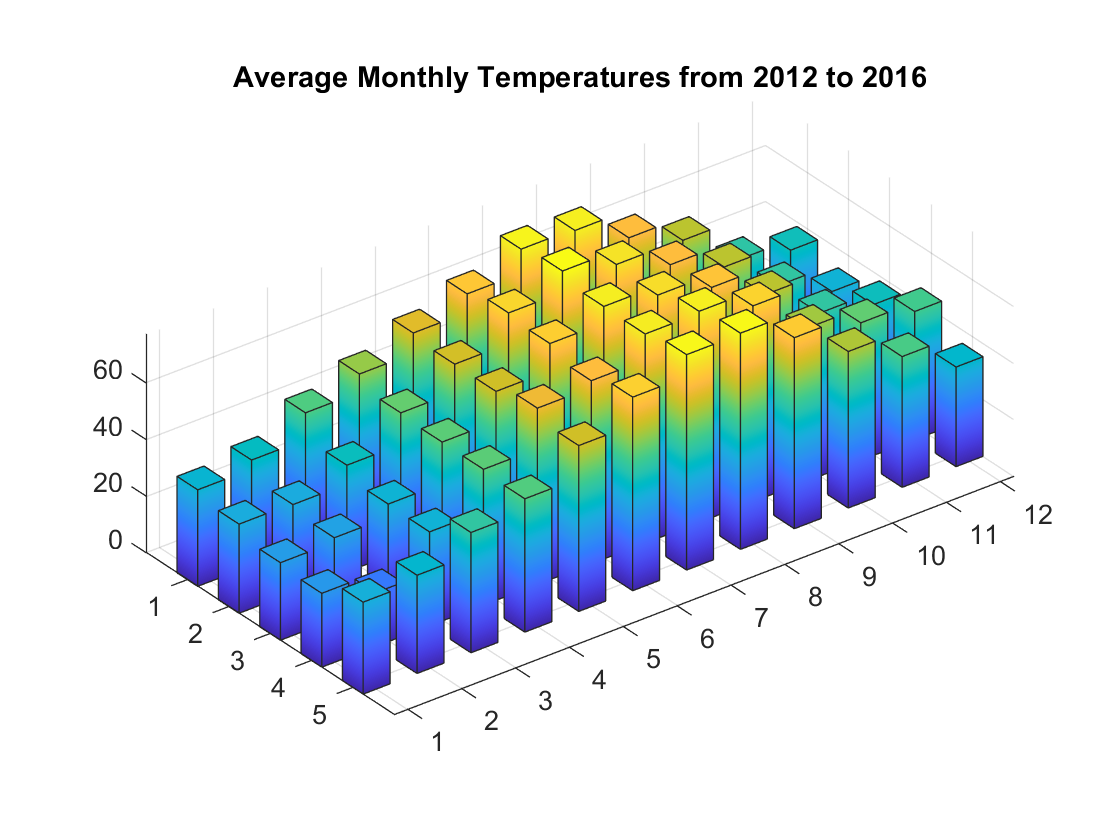

barWidth = 0.5;
figure
b = bar3(TempData5Years,barWidth);      % Specify bar width in the third argument

for k = 1:length(b)
    zdata = b(k).ZData;                 % Use ZData property to create color gradient
    b(k).CData = zdata;                 % Set CData property to Zdata
    b(k).FaceColor = "interp";          % Set the FaceColor to 'interp' to enable the gradient 
end
title(sprintf("Average Monthly Temperatures from %d to %d",Year(yearIdx),Year(yearIdx+4)))

### Customize Axes

Add axes labels, custom axes tick labels using the `x `and `yticklabels `commands. Use `box`* on* to create a bounding box around the axes.

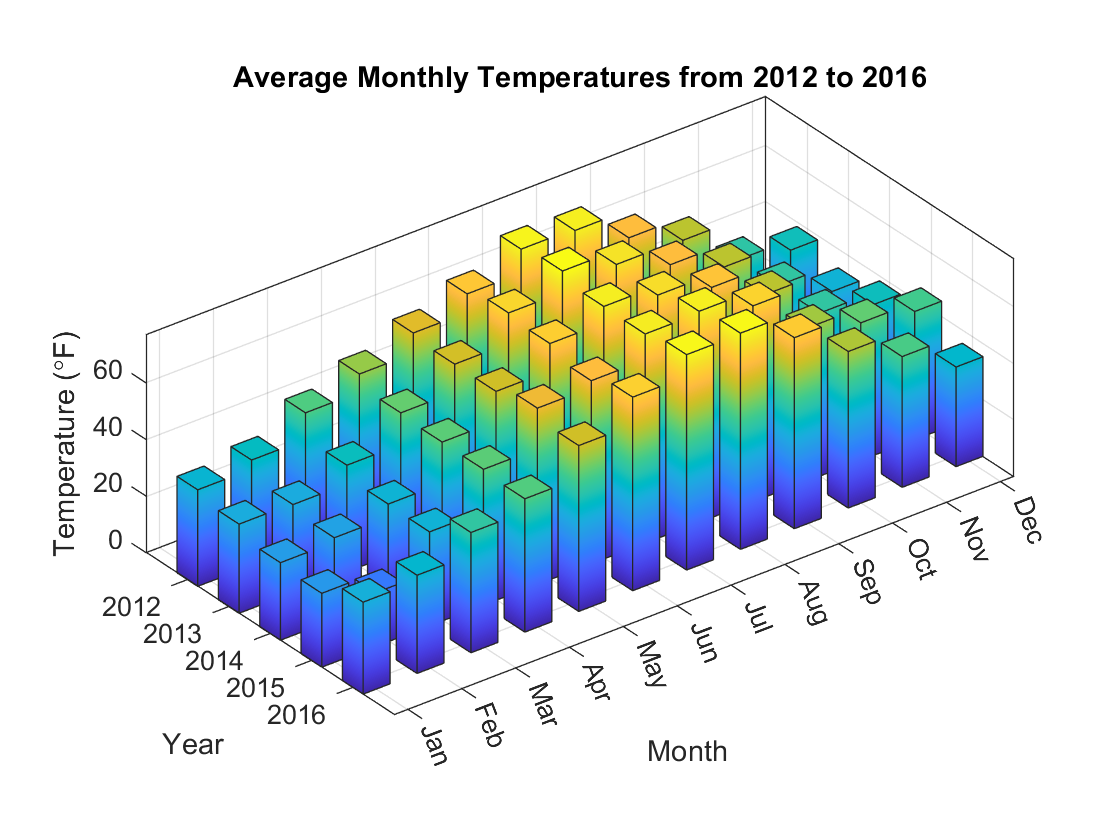

xlabel("Month")
ylabel("Year")
zlabel("Temperature (\circF)")

xticklabels(Months)
yticklabels(Year(yearIdx):Year(yearIdx+4))

box on

## **Additional Information**

### **Get All Surface Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a Surface, uncomment the following code. View or modify these properties using dot notation.

% get(b(1))

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[3-D Vertical Bar Graph](https://www.mathworks.com/help/matlab/ref/bar3.html)

Copyright (c) 2021, The MathWorks, Inc.